% topographical maps
% mikeXcohen@gmail.com

## load in EEG data

load sampleEEGdata.mat

## introduction to topographical plotting

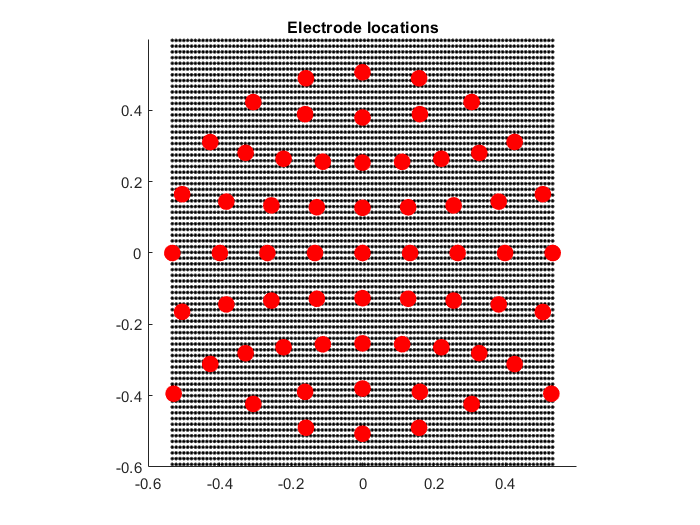

% get cartesian coordinates
[elocsX,elocsY] = pol2cart(pi/180*[EEG.chanlocs.theta],[EEG.chanlocs.radius]);

% plot electrode locations
figure(1), clf
scatter(elocsY,elocsX,100,'ro','filled');
set(gca,'xlim',[-.6 .6],'ylim',[-.6 .6])
axis square
title('Electrode locations')


% define XY points for interpolation
interp_detail = 100;
interpX = linspace(min(elocsX)-.2,max(elocsX)+.25,interp_detail);
interpY = linspace(min(elocsY),max(elocsY),interp_detail);

% meshgrid is a function that creates 2D grid locations based on 1D inputs
[gridX,gridY] = meshgrid(interpX,interpY);

% let's look at these matrices
hold on
plot3(gridY(:),gridX(:),-ones(1,interp_detail^2),'k.')

## extract data and interpolate to 2D grid

timepoint2plot = 100; % in ms

% convert time point from ms to index
[~,timepointidx] = min(abs(EEG.times-timepoint2plot));

% data from this frequency from some other matrix
dat = double( mean(EEG.data(:,timepointidx,:),3) );

% now interpolate the data on a 2D grid
interpFunction = TriScatteredInterp(elocsY',elocsX',dat);
%interpFunction = scatteredInterpolant(elocsY',elocsX',dat);
topodata = interpFunction(gridX,gridY);

## plot results

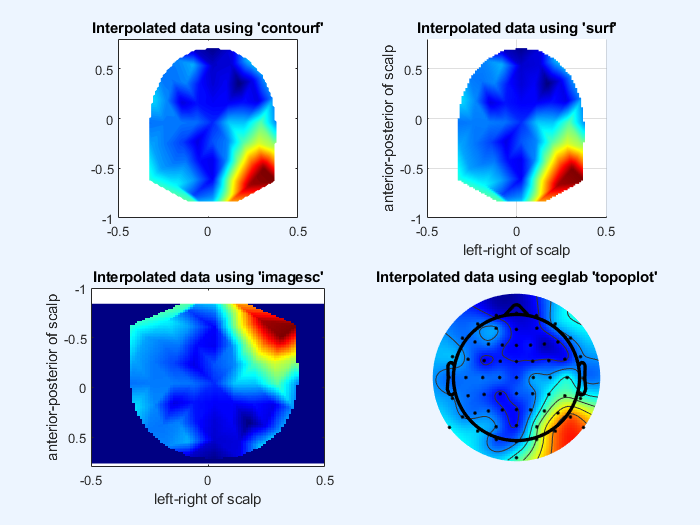

figure(2), clf

% contourf
subplot(221)
contourf(interpY,interpX,topodata,100,'linecolor','none');
axis square
set(gca,'xlim',[-.5 .5],'ylim',[-1 .8])
title('Interpolated data using ''contourf''')

% surface
subplot(222)
surf(interpY,interpX,topodata);
xlabel('left-right of scalp'), ylabel('anterior-posterior of scalp'), zlabel('\muV')
shading interp, axis square
set(gca,'xlim',[-.5 .5],'ylim',[-1 .8])
rotate3d on, view(0,90)
title('Interpolated data using ''surf''')

% pixelated image
subplot(223)
imagesc(interpY,interpX,topodata);
xlabel('left-right of scalp'), ylabel('anterior-posterior of scalp'), zlabel('\muV')
set(gca,'xlim',[-.5 .5],'ylim',[-1 .8])
title('Interpolated data using ''imagesc''')

% eeglab function
subplot(224)
topoplot(dat,EEG.chanlocs); % eeglab's topoplot function
title('Interpolated data using eeglab ''topoplot''')

## useful bit of code to see channel locations

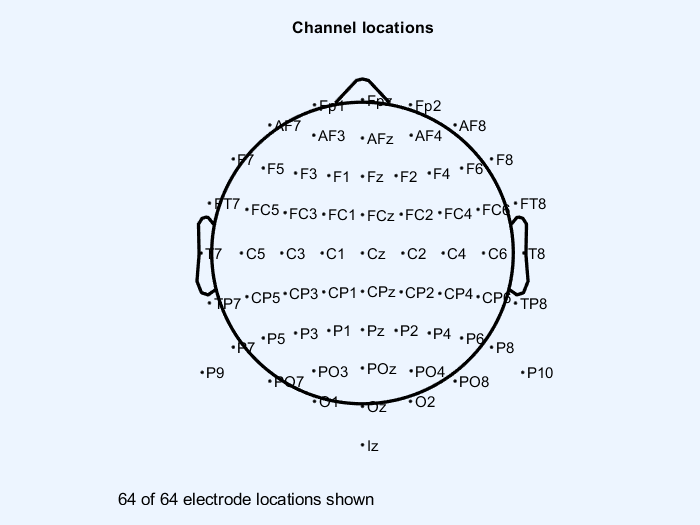

figure
topoplot([],EEG.chanlocs,'electrodes','ptslabels');

% hint: click on an electrode to see its corresponding index (number)

## end.